## BOW Physiognomy

Sam Coleman and Caitlin Kantor

clear vars
clear
clf
clc

% MAYBE TRY non negative matrix factorization
% Create matrices for each institution
%commented out because we loaded it into a mat file

% for k = 1:75
%     pngFilename = sprintf('Br%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         B = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         B = reshape(B, [], 1);
%     end
%     Ball(:, k) = B;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Or%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         O = double(rgb2gray(imread(fullFileName)))/255.0;
%         O = reshape(O, [], 1);
%     end
%     Oall(:, k) = O;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Wr%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         W = double(rgb2gray(imread(fullFileName)))/255.0;
%         W = reshape(W, [], 1);
%     end
%     Wall(:, k) = W;
% end
% 
% save('TrainingData.mat', 'Ball', 'Oall', 'Wall')

%load B, O, W training data matrices
load TrainingData.mat

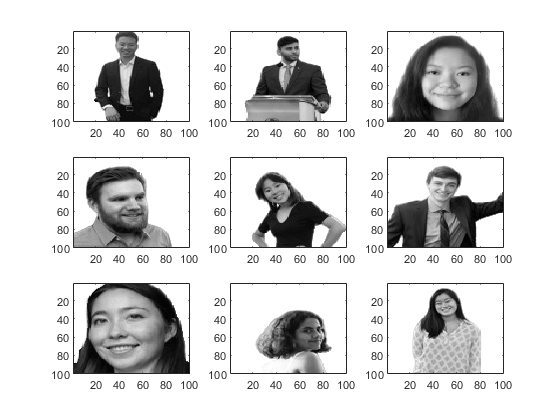

figure()
subplot(3, 3, 1)
imagesc(reshape(Ball(:, 1), [100 100]))
colormap('gray')
subplot(3, 3, 2)
imagesc(reshape(Ball(:, 22), [100 100]))
colormap('gray')
subplot(3, 3, 3)
imagesc(reshape(Ball(:, 54), [100 100]))
colormap('gray')
subplot(3, 3, 4)
imagesc(reshape(Oall(:, 15), [100 100]))
colormap('gray')
subplot(3, 3, 5)
imagesc(reshape(Oall(:, 50), [100 100]))
colormap('gray')
subplot(3, 3, 6)
imagesc(reshape(Oall(:, 68), [100 100]))
colormap('gray')
subplot(3, 3, 7)
imagesc(reshape(Wall(:, 5), [100 100]))
colormap('gray')
subplot(3, 3, 8)
imagesc(reshape(Wall(:, 26), [100 100]))
colormap('gray')
subplot(3, 3, 9)
imagesc(reshape(Wall(:, 55), [100 100]))
colormap('gray')

%Turn matrices into column vectors
%BCol = reshape(B, [100*100, 75])';
BCol = Ball';
OCol = Oall';
WCol = Wall';
% OCol = reshape(O, [100*100, 75])';
% WCol = reshape(W, [100*100, 75])';

%Make mean centered
BCol = BCol - mean(BCol);
OCol = OCol - mean(OCol);
WCol = WCol - mean(WCol);

AllCol = cat(1, BCol, OCol, WCol);

%Find covariance matrices
Ba = (1/sqrt(9999)) * BCol;
Br = Ba' * Ba;
Oa = (1/sqrt(9999)) * OCol;
Or = Oa' * Oa;
Wa = (1/sqrt(9999)) * WCol;
Wr = Wa' * Wa;


Aa = (1/sqrt(9999)) * AllCol;
Ar = Aa' * Aa;

%Find eigenvectors (and values)
% [BV, BD] = eigs(Br, 40);
% Bbodies = BV;
% [OV, OD] = eigs(Or, 40);
% Obodies = OV;
% [WV, WD] = eigs(Wr, 40);
% Wbodies = WV;

[AV, AD] = eigs(Ar, 225)

AV =    -0.0040   -0.0238   -0.0232    0.0235    0.0144   -0.0164   -0.0253    0.0133    0.0409    0.0356   -0.0376    0.0310    0.0398   -0.0690    0.0232    0.0469    0.0086    0.0335    0.0136   -0.0642   -0.0786   -0.1084   -0.0207   -0.0711   -0.0463    0.0269    0.0017   -0.0713   -0.1432   -0.0451   -0.1676    0.0974    0.1697   -0.1046   -0.2455    0.1278   -0.1160   -0.1786    0.1314    0.0977   -0.2473   -0.1814    0.1001    0.1169   -0.1221    0.0765    0.0895   -0.0139   -0.1241    0.2248
   -0.0052   -0.0121   -0.0126    0.0128    0.0096   -0.0070   -0.0177    0.0083    0.0264    0.0227   -0.0263    0.0193    0.0227   -0.0371    0.0122    0.0323    0.0160    0.0249    0.0016   -0.0341   -0.0498   -0.0632   -0.0136   -0.0375   -0.0294    0.0195   -0.0020   -0.0428   -0.0972   -0.0275   -0.1055    0.0609    0.1068   -0.0653   -0.1537    0.0799   -0.0727   -0.1127    0.0819    0.0600   -0.1538   -0.1132    0.0613    0.0712   -0.0771    0.0489    0.0559   -0.0092   -0.0770    

AD =     2.4795         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.7484         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

AllBodies = AV;

%See the eigenbodies
% for i = 1:40
%     figure()
%     hold on
%     imagesc(reshape(AllBodies(:, i), [100, 100]))
%     colormap('gray')
%     axis ij
%     hold off
% end

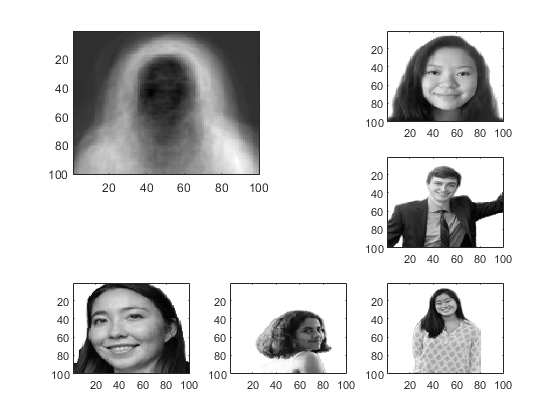

subplot(2, 2, 1)
imagesc(reshape(AllBodies(:, 1), [100, 100]))
colormap('gray')
axis ij

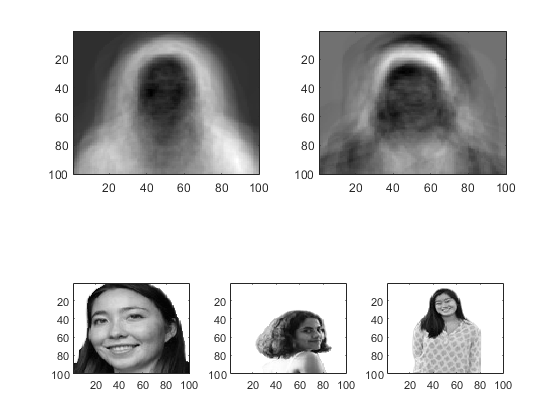

subplot(2, 2, 2)
imagesc(reshape(AllBodies(:, 10), [100, 100]))
colormap('gray')

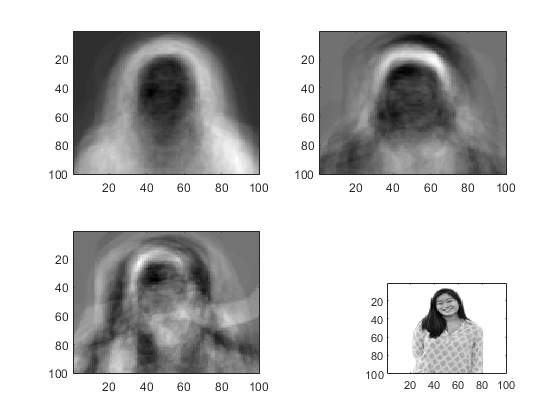

subplot(2, 2, 3)
imagesc(reshape(AllBodies(:, 20), [100, 100]))
colormap('gray')
axis ij

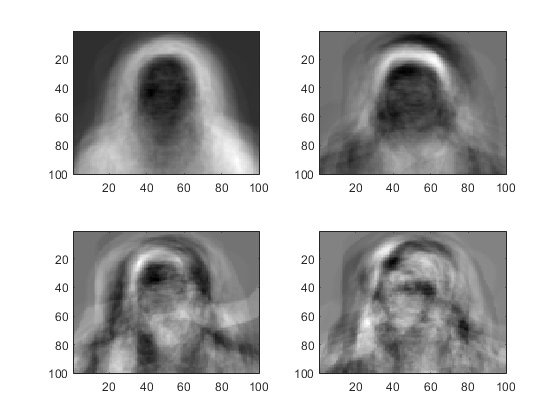

subplot(2, 2, 4)
imagesc(reshape(AllBodies(:, 30), [100, 100]))
colormap('gray')
axis ij

%Create into body space
% b_train = BCol * Bbodies;
% o_train = OCol * Obodies;
% 
% w_train = WCol * Wbodies;

all_train = AllCol * AllBodies;

% %Prepare Test Data
% counter = 0
% for k = 76:100
%     counter = counter + 1;
%     pngFilename = sprintf('Br%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% counter = 25
% for k = 76:100
%     counter = counter + 1;
%     pngFilename = sprintf('Or%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% counter = 50
% for k = 76:100
%     counter = counter + 1
%     pngFilename = sprintf('Wr%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% %Babson is 0, Olin is 1, Wellesley is 2 in answer matrix
% answerMatrix = ones([75 1]);
% counter = 0;
% for k = 1:25
%     counter = counter + 1;
%     answerMatrix(counter, 1) = 0;
% end
% 
% counter = 50;
% for k = 1:25
%     counter = counter + 1;
%     answerMatrix(counter, 1) = 2;
% end
% 
% save('Bow_test_data.mat', 'BOW_test_all', 'answerMatrix')

%Load test data
load Bow_test_data.mat

%Prepare test data for anaylsis
BOW_test_all = BOW_test_all - mean(BOW_test_all);
%BOW_test_all = BOW_test_all';
bow_test = BOW_test_all' * AllBodies;

results = knnsearch(all_train, bow_test)

results =     47
    30
   201
   201
    40
    77
    99
    47
    77
    19


% for i = 1:75
%     indexTrain= results(i);
%     figure()
%     image = reshape(AllCol(indexTrain, :), [100 100]);
%     subplot(1,2,1)
%     imagesc(image)
%     colormap('gray')
%     axis equal
%     title(indexTrain)
%     subplot(1,2,2)
%     image = reshape(BOW_test_all(:, i), [100 100]);
%     imagesc(image)
%     colormap('gray')
%     axis equal
%     title(i)
% end

for i = 1:75
    results(i) = idivide(int16(results(i)), int16(75));
end

for i = 1:75
    if results(i) == 3
        results(i) = 2;
     end
end
results

results =      0
     0
     2
     2
     0
     1
     1
     0
     1
     0


accuracy = mean(answerMatrix == results)

accuracy = 0.4000

## Determine Accuracy of Method 1

accuracies1 = ones(225, 1);
[AV1, AD1] = eigs(Ar, 225);

for num_components = 1:225
    num_components;
    AllBodies1 = AV1(:, 1:num_components);
    all_train1 = AllCol * AllBodies1;
    BOW_test_all1 = BOW_test_all - mean(BOW_test_all);
    bow_test1 = BOW_test_all1' * AllBodies1;
    
    results1 = knnsearch(all_train1, bow_test1);
    for i = 1:75
        results1(i) = idivide(int16(results1(i)), int16(75));
    end

    for i = 1:75
        if results1(i) == 3
            results1(i) = 2;
        end
    end
    
    accuracies1(num_components) = mean(answerMatrix == results1);
end

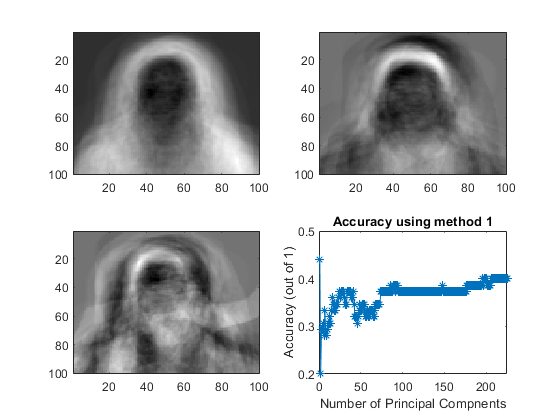

%Plot Accuracy
plot(accuracies1, '*-')
title('Accuracy using method 1')
xlabel('Number of Principal Compnents')
ylabel('Accuracy (out of 1)')

% %Create plot for #principal components vs accuracy
% accuracies1 = ones(75, 1);
% for i = 1:225
%     i
%     [AV1, AD1] = eigs(Ar, i);
%     AllBodies1 = AV1;
%     all_train1 = AllCol * AllBodies1;
%     BOW_test_all1 = BOW_test_all - mean(BOW_test_all);
%     bow_test1 = BOW_test_all1' * AllBodies1;
%     
%     results = knnsearch(all_train, bow_test);
%     for k = 1:75
%         results(k) = idivide(int16(results(k)), int16(75));
%     end
% 
%     for k = 1:75
%         if results(k) == 3
%             results(k) = 2;
%         end
%     end
%     accuracies1(i) = mean(answerMatrix == results);
% end

## Confusion Matrix

BPredNum = 0

BPredNum = 0

OPredNum = 0

OPredNum = 0

WPredNum = 0

WPredNum = 0

for i = 1:75
    if results(i) == 0
        BPredNum = BPredNum + 1;
    end
    if results(i) == 1
        OPredNum = OPredNum + 1;
    end
    if results(i) == 2
        WPredNum = WPredNum + 1;
    end
end

BPredNum

BPredNum = 31

OPredNum

OPredNum = 24

WPredNum

WPredNum = 20


BPredNum + OPredNum + WPredNum

ans = 75


%BPredNum = BPredNum / 25
%OPredNum = OPredNum / 25
%WPredNum = WPredNum / 25
%BPredNum + OPredNum + WPredNum

%%Create a box around faces
% scaleFactor = 25;
% locationFactor = -.5*scaleFactor;
% test = reshape(Ball(:, 20), [100 100]);
% size(test);
% faceDetector = vision.CascadeObjectDetector;
% Testbox = step(faceDetector, test) %+ [locationFactor locationFactor scaleFactor scaleFactor];
% imagesc(test)
% colormap('gray')
% vision.ShapeInserter('BorderColor', 'Custom', 'CustomBorderColor',[255 255 0]);
% TestFaces = step(vision.ShapeInserter, test, int32(Testbox)); 
% figure, imagesc(TestFaces), title('Detected faces');
% colormap('gray')
% axis 'square'

% testCrop = imcrop(test, Testbox);
% imshow(testCrop)